clc;
clear;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 在真实场景 Cube 中，
% 根据BESTAnP, Non-app, app 和 Combine_CIO算法的估计结果
% 画重投影图
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

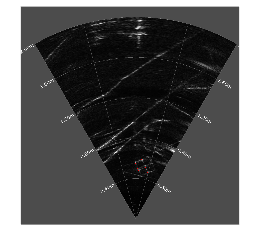

% 方块第4组数据
I=imread('D:\BESTAnP-main\MatabCode\Experiments\reprojection experiments\4.png');
imshow(I)

p_si = [764	894
781	934
800	973
757	988
716	1003
723	920
743	959
684	936
702	974
721	912
739	950
680	927
697	966
];

% ToCAnP AnP估计的坐标
p_si_est_my =[761.5095835	893.3320843
779.8469265	932.7479783
799.129911	971.2779702
756.4994496	987.5753284
713.3120407	1004.274808
722.9902195	917.9261833
740.2068511	959.1345885
681.708698	936.4646871
698.9196835	975.6582178
719.4422406	910.5713816
737.519626	949.6538166
677.2741944	927.1271739
694.9516188	966.9421552

];





% Nonapp 估计的坐标
p_si_est_Nonapp =[761.9798914	904.316066
777.1221018	945.0609569
792.785505	984.7956147
750.725996	1000.009125
708.5921285	1015.357927
723.8629247	923.3490054
738.7412136	965.8302958
681.8755102	939.5546996
696.9161901	980.0970418
720.207138	919.7192943
735.2664389	960.4339353
678.4481227	934.2075595
693.4234902	975.8995561

];


% app 估计的坐标
p_si_est_app = [762.2960831	893.5992992
779.3413657	932.9397268
796.9571881	971.0714516
755.720313	987.9902672
714.3741234	1004.991353
724.6513892	917.4634195
741.4585089	958.871192
683.3036365	935.7214832
700.3231141	975.1488322
721.2806235	910.8208069
738.2714179	950.086183
680.2750971	927.0950496
697.1946097	967.2986244

];

p_si_est_CIO = [761.5855742	893.5615186
778.9130334	933.0666572
796.7774138	971.4292839
755.6215179	988.2997379
714.3453353	1005.218863
722.5867601	916.9830815
739.7126607	958.4064723
681.3011658	935.377123
698.6088304	974.7943263
720.6172565	910.7769859
737.9008738	950.1827211
679.6524676	927.0330375
696.8721919	967.3449536

];


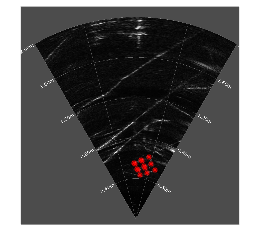

figure,imshow(I)
hold on; % 保持图像，以便叠加绘制
scatter(p_si(:,1),p_si(:,2),15,'MarkerEdgeColor',[1,0,0],'Marker', '*');
xlabel('Ground Truth','FontSize', 30)

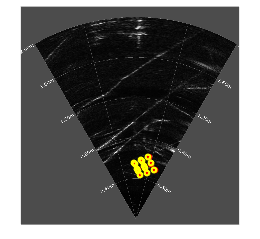


% ToCAnP AnP 绘制点到图像上 
figure,imshow(I)
hold on; % 保持图像，以便叠加绘制
scatter(p_si(:,1),p_si(:,2),20,'MarkerEdgeColor',[1,0,0],'Marker', '*','LineWidth', 1.5);
scatter(p_si_est_my(:,1),p_si_est_my(:,2),10,'MarkerEdgeColor',[1,1,0],'Marker', 'o','LineWidth', 1.5);

% 遍历每对点，绘制连线
for i = 1:size(p_si, 1)
    plot([p_si_est_my(i, 1), p_si(i, 1)], [p_si_est_my(i, 2), p_si(i, 2)], 'y--'); % 连接对应点的线
end

% xlabel('Two-step AnP Algorithm','FontSize', 30)

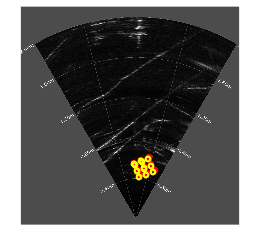

% Nonapp AnP 绘制点到图像上 
figure,imshow(I)
hold on; % 保持图像，以便叠加绘制
scatter(p_si(:,1),p_si(:,2),20,'MarkerEdgeColor',[1,0,0],'Marker', '*','LineWidth', 1.5);
scatter(p_si_est_Nonapp(:,1),p_si_est_Nonapp(:,2),10,'MarkerEdgeColor',[1,1,0],'Marker', 'o','LineWidth', 1.5);

% 遍历每对点，绘制连线
for i = 1:size(p_si, 1)
    plot([p_si_est_Nonapp(i, 1), p_si(i, 1)], [p_si_est_Nonapp(i, 2), p_si(i, 2)], 'y--'); % 连接对应点的线
end

%xlabel('Non-app Algorithm','FontSize', 30)

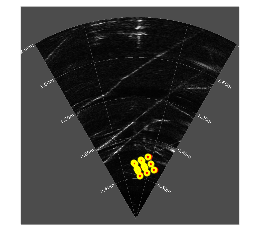

% App AnP 绘制点到图像上 
figure,imshow(I)
hold on; % 保持图像，以便叠加绘制
scatter(p_si(:,1),p_si(:,2),20,'MarkerEdgeColor',[1,0,0],'Marker', '*','LineWidth', 1.5);
scatter(p_si_est_app(:,1),p_si_est_app(:,2),10,'MarkerEdgeColor',[1,1,0],'Marker', 'o','LineWidth', 1.5);

% 遍历每对点，绘制连线
for i = 1:size(p_si, 1)
    plot([p_si_est_app(i, 1), p_si(i, 1)], [p_si_est_app(i, 2), p_si(i, 2)], 'y--'); % 连接对应点的线
end

%xlabel('App Algorithm','FontSize', 30)

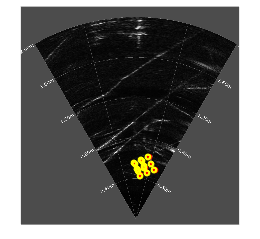

% CIO AnP 绘制点到图像上 
figure,imshow(I)
hold on; % 保持图像，以便叠加绘制
scatter(p_si(:,1),p_si(:,2),20,'MarkerEdgeColor',[1,0,0],'Marker', '*','LineWidth', 1.5);
scatter(p_si_est_CIO(:,1),p_si_est_CIO(:,2),10,'MarkerEdgeColor',[1,1,0],'Marker', 'o','LineWidth', 1.5);

% 遍历每对点，绘制连线
for i = 1:size(p_si, 1)
    plot([p_si_est_CIO(i, 1), p_si(i, 1)], [p_si_est_CIO(i, 2), p_si(i, 2)], 'y--'); % 连接对应点的线
end

%xlabel('App Algorithm','FontSize', 30)